# PHSCS 560

## HW: Functions

### Problem 1: Expanding and Interpolating Functions

Part A: Taylor Series Approximation

% anonymous function for Taylor series of sin(x) with N terms
sinTaylor = @(x,N) sum((-1).^((1:N)-1) .* x.^(2*(1:N)-1) ./ factorial(2*(1:N)-1),2);

% create 10^6 randomly distributed points between 0 and 2\pi
xq = 2*pi*rand(1e6,1);

tic
trueResult = sin(xq);
tTrue = toc;

N = [3,10,30,100];
for i = 1:length(N)
    tic
    approx = sinTaylor(xq,N(i));
    tTaylor(i) = toc;
    errTaylor(i) = rms(approx - trueResult);
end

Part B: Linear Interpolation

for i = 1:length(N)
    x = linspace(0,2*pi,N(i));
    tic
    approx = linterp(x,sin(x),xq);
    tInterp(i) = toc;
    errInterp(i) = rms(approx - trueResult);
end

rowNames = cell(2*length(N),1);
for i = 1:length(N)
    rowNames{i} = ['Taylor Series, N = ',num2str(N(i))];
    rowNames{i+length(N)} = ['Linear Interp, N = ',num2str(N(i))];
end
colNames = {'RMS Error','Time (s)'};
T = table([errTaylor,errInterp]',[tTaylor,tInterp]','RowNames',rowNames,'VariableNames',colNames)

T = 8×2 table
                              RMS Error     Time (s)
                              __________    ________

    Taylor Series, N = 3          12.717    0.18135 
    Taylor Series, N = 10     0.00016051    0.51366 
    Taylor Series, N = 30     2.6758e-15     1.3478 
    Taylor Series, N = 100    2.6758e-15     4.3091 
    Linear Interp, N = 3         0.70738    0.15691 
    Linear Interp, N = 10       0.031146    0.20247 
    Linear Interp, N = 30      0.0030291    0.44178 
    Linear Interp, N = 100    0.00026005     1.3119 


So, the Taylor series seems to be more accurate than the linear interpolation scheme with the same number of terms; however, the linear interpolation (at least as I have coded it up) appears to be increasingly faster than the Taylor series for large N.

### Problem 2: Numerical Definite Integrals (Quadrature)

#### Part A: Black-Box Integration

I'm using MATLAB's *integraI* function, which uses global adaptive quadrature to do the numerical integration.

f = @(x) exp(-cos(x));              % anonymous function f(x)
g = @(x) f(x) .* (abs(x) <= 1);     % anonymous function g(x), defined piecewise

Ia = [integral(f,-pi,pi),...   % I1
      integral(f,-1,1),...     % I2
      integral(g,-pi,pi)];     % I3

Iexact = [7.9549265210128452745132196653294,...
          0.87070265620795901020832433774759,...
          0.87070265620795901020832433774759];

IaErr = Ia - Iexact

IaErr =   -8.8818e-16  -2.2204e-16  -1.1113e-07


So, we got the first two integrals within machine precision of the decimal approximations. However, the third integral has an error of about 9 orders of magnitude greater than machine precision. So, it looks like the first two converge nicely, while the third is numerically difficult.

#### Part B: Trapezoid Rule and Convergence

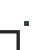

N = 2.^(0:10); % number of points
Ib = zeros(length(N),3); % initialze empty integral result array
for i = 1:length(N)
    Ib(i,:) = [trap(f,linspace(-pi,pi,N(i)+1));...
        trap(f,linspace(-1,1,N(i)+1));...
        trap(g,linspace(-pi,pi,N(i)+1))];
end

% plot result
figure
loglog(N,abs(Ib - Iexact))
xlabel('N')
ylabel('Absolute Relative Error')
grid on
legend('I_1','I_2','I_3')

### Problem 3: Periodic and Spherical Integrals

#### Part A: Optimal Parameters for Periodic Integration

Let us construct a basis for our Gaussian quadrature where $P=\left\lbrace 1,\;\cos \left(x\right),\;\sin \left(x\right)\;,\cos \left(2x\right)\;,\sin \left(2x\right)\;,\ldotp \ldotp \ldotp ,\;\cos \left(nx\right),\;\sin \left(nx\right)\right\rbrace =\left\lbrace P_0 ,P_1 ,P_2 ,P_3 ,P_4 ,\ldotp \ldotp \ldotp ,P_{N-1} ,P_N \right\rbrace \ldotp$

Now, our abscissas come from the roots of $P_N =\sin \left(nx\right)$. It has $N=2n$ zeros that are equally spaced at values $x_j =\frac{j\pi }{n}=\frac{2j\pi }{N}$

We know that $w_j =\frac{\left\langle P_{N-1} \;|\;P_{N-1} \right\rangle }{P_{N-1} \left(x_j \right)\;P_N^{\prime } \left(x_j \right)},$so,


$$w_j =\frac{\int_0^{2\pi \;} \cos^2 \left(nx\right)\;dx}{\cos \left({nx}_j \right)\;n\;\cos \left({nx}_j \right)}=\frac{2\int_0^{2\pi \;} \cos^2 \left(\frac{Nx}{2}\right)\;dx}{\cos \left(\frac{{Nx}_j }{2}\right)\;n\;\cos \left(\frac{{Nx}_j }{2}\right)}=\frac{2\pi }{{N\left(\cos \left(\pi j\right)\right)}^2 }=\frac{2\pi }{N}=\frac{\pi }{n}$$


#### Part B: Spherical Integration

For the Gauss-Legendre quadrature in the variable $\cos \left(\theta \right)$, the abscissas come from the roots of $P_M =P_M \left(\cos \left(\theta \;\right)\right)\ldotp$ we have the weights


$$w_i =\frac{2}{\left(1-x_i^2 \right){\left\lbrack P_m^{\prime } \left(x_i \right)\right\rbrack }^2 }=\frac{2\left(1-x_i^2 \right)}{{\left(m+1\right)}^2 {\left\lbrack P_{m+1} \left(x_i \right)\right\rbrack }^2 }$$



$$I=\frac{\pi }{n}\sum_{j=1}^{2n} \sum_{i=1}^m w_{i\;} f\left(\theta_i ,\phi_j \right)$$


where $f\left(\theta_i ,\phi_j \right)=\cos^2 \left(\theta_i \right)\;\sin^2 \left(\phi_j \right)$


$$I=\frac{2\pi }{n}\sum_{j=1}^{2n} \sin^2 \left(\frac{j\pi }{n}\right)\sum_{i=1}^m \frac{\cos^2 \left(\theta_i \right)\;\left(1-\cos^2 \left(\theta_i \right)\right)}{{\left(m+1\right)}^2 {\left\lbrack P_{m+1} \left(\cos \left(\theta_i \right)\right)\right\rbrack }^2 }$$


% zeros of P_m(x) (abscissas) and their respective weight functions for m =
% 1 to m = 5. From tabulated data at
% https://mathworld.wolfram.com/Legendre-GaussQuadrature.html

m.xi{2} = [sqrt(3)/3,...
           -sqrt(3)/3];
m.wi{2} = [1,...
           1];

m.xi{3} = [0,...
           sqrt(15)/5,...
           -sqrt(15)/5];
m.wi{3} = [8/9,...
           5/9,...
           5/9];

m.xi{4} = [sqrt(525 - 70*sqrt(30))/35,...
           -sqrt(525 - 70*sqrt(30))/35,...
           sqrt(525 + 70*sqrt(30))/35,...
           -sqrt(525 + 70*sqrt(30))/35];
m.wi{4} = [(18 + sqrt(30))/36,...
           (18 + sqrt(30))/36,...
           (18 - sqrt(30))/36,...
           (18 - sqrt(30))/36];

m.xi{5} = [0,...
    sqrt(245 - 14*sqrt(70))/21,...
    -sqrt(245 - 14*sqrt(70))/21,...
    sqrt(245 + 14*sqrt(70))/21,...
    -sqrt(245 + 14*sqrt(70))/21];
m.wi{5} = [128/225,...
    (322 + 13*sqrt(70))/900,...
    (322 + 13*sqrt(70))/900,...
    (322 - 13*sqrt(70))/900,...
    (322 - 13*sqrt(70))/900];

% make change of variables x -> theta from P_m(x) to P_m(cos(theta))
for i = 2:5
    m.thetai{i} = acos(m.xi{i});
end

% construct the sum in m (theta)
% summ = @(thetai,m,wi) sum(cos(thetai).^2 .* (1 - cos(thetai).^2) ./...
%     (([1:m] + 1).^2 .* (legendreP([1:m],cos(thetai))).^2));
summ = @(thetai,m,wi) sum(cos(thetai).^2 .* wi);
sumn = @(n,m,thetai,wi) pi/n * sum(sin([1:2*n]*pi/n).^2 .* summ(thetai,m,wi));

res = sumn(5,5,m.thetai{5},m.wi{5})

res =        2.0944


### Problem 4: Summing Series

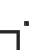

N = 2.^(0:22); % number of points

sinf = pi/4;
for i = 1:length(N)
    sn(i) = s(N(i));
    snp(i) = sAitken(N(i));
end
% plot result
figure
loglog(N,abs(sn - sinf),'DisplayName','s_n')
hold on
loglog(N,abs(snp - sinf),'--','DisplayName','Aitken \Delta^2 s_n''')
hold off
xlabel('N')
ylabel('Absolute Relative Error')
grid on
legend('AutoUpdate','off')
yline(1e-7,':k','LineWidth',1.5,'Label','10^{-7}')
xlim([N(1),N(end)])

So, the standard direct sum routine requires approximately $2\cdot {10}^{6\;}$terms to converge within ${10}^{-7}$. However, Aitken's method only requires roughly 100 terms to achieve this same level of convergence!

### Functions

function yq = linterp(x,y,xq)
    % Linear Interpolation Scheme
    % INPUTS
    %   x - input vector of sample points
    %   y - input vector of function points
    %   xq - vector of query sample points to interpolate to
    % OUTPTS
    %   yq - vector of linearly interpolated function points\

    % enforce column vectors
    x = x(:);
    y = y(:);
    xq = xq(:);
    
    % find indices of two closest points in x for each point in xq
    [~,ind] = sort(abs(x - xq'),1);
    % make sure bounds are ordered from lower to higher
    bounds = sort(ind(1:2,:));
    
    yq = y(bounds(1,:)) + (xq - x(bounds(1,:))) .*...
        (y(bounds(2,:)) - y(bounds(1,:))) ./ ...
        (x(bounds(2,:)) - x(bounds(1,:)));
end

function int = trap(fun,pts)
    dx = pts(2:end) - pts(1:end-1); % spacing between grid points
    int = sum((fun(pts(1:end-1)) + fun(pts(2:end)))/2 .* dx); % trapezoid rule
end

function sn = s(n)
    jj = 0:n;
    sn = sum(((-1).^jj) ./ (2*jj + 1));
end

function snp = sAitken(n)
    sn = s(n);
    sn1 = s(n+1);
    sn2 = s(n+2);

    snp = sn - (sn1 - sn).^2 ./ (sn2 - 2*sn1 + sn);
end